# **WSN Simulation and Calculating Network's Lifetime **

### **This project is a simulation for a wireless sensor network (WSN) consisting of 100 sensor nodes that are randomly deployed in a homogeneous manner. The sensors have limited energy resources, and the sink is placed either at the center of the network or at one of its corners. The sensor nodes transmit data to the sink, which depletes their energy, causing them to die at different points in time.**

### **- In this project, we will analyze and demonstrate the following:**

- The network topology with the sink located either at the center or at one of the corners.

- The number of active nodes versus the number of cycles (network lifetime).

- The Cycle at which the first node dies, half of the nodes died, and the last node dies.

- The remaining energy of each node after each cycle . 

- **Clearing the working space, Close whole figures, before starting : **

close all ; 
clear all; 
clc ; 

- **Defining the Parameters that will be used across the scope of the project : **

% Parameters
N = 100;                                % Number of nodes
A = 100;                                % Area size (100m x 100m)
x = randi([0, A], 1, N);                % X coordinates of nodes (whole numbers)
y = randi([0, A], 1, N);                % Y coordinates of nodes (whole numbers)
E_initial = 2;                          % Initial energy (2 joules for each node)
sink = [A/2,A/2];                       % Sink is located at the center
sink_corner= [100,100];                 % Sink is located at the top right corner 
Eelec = 50e-9;                          % Energy to run transmitter/receiver circuitry (J/bit)
epsilon_fs = 10e-9;                     % Free space model energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                 % Multi-path model energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);     % Threshold distance
k = 4000;                               % Number of bits transmitted per cycle

% Initialize node energy and position
E = E_initial * ones(1, N);              % Energy of all nodes (in Joules)
E_corners = E_initial * ones(1, N);      % Energy of all nodes (in Joules) for sink within corner 
remaining_energy = zeros(N, 1);          % Track remaining energy at each cycle
remaining_energy_corners = zeros(N, 1);  % Track remaining energy at each cycle for sink within corner 
alive_nodes = N;                         % Number of active nodes
alive_nodes_corners = N;                 % Number of active nodes for sink within corner 
alive_nodes_per_cycle = [];              % Store active nodes per cycle
alive_nodes_per_cycle_corners = [];      % Store active nodes per cycle for sink within corner 
remaining_energy_per_cycle = [];         % Track remaining energy per cycle
remaining_energy_per_cycle_corners = []; % Track remaining energy per cycle for sink within corner 
cycles = 0;                              % Cycle count
cycles_corners = 0;                      % Cycle count for sink within corner 
node_dead= false(1, N);                  % Track dead nodes
node_dead_corners = false(1, N);         % Track dead nodes for sink within corner 

% Preallocate arrays for dead node indices due to sink in the Center 
dead_nodes_T1 = [];                      % Allocate the indicies of dead nodes through the first Cycle 
dead_nodes_T2 = [];                      % Allocate the indicies of dead nodes through the second cycle 
dead_nodes_T3 = [];                      % Allocate the indicies of dead nodes through the thrid cycle 


% Preallocate arrays for dead node indices due to sink in the corner 
dead_nodes_T1_corners = [];                      % Allocate the indicies of dead nodes through the first Cycle 
dead_nodes_T2_corners = [];                      % Allocate the indicies of dead nodes through the second cycle 
dead_nodes_T3_corners = [];                      % Allocate the indicies of dead nodes through the thrid cycle 

**Part A ****  The network topology with 100 sensors randomly deployed , with the sink at the center :                                                                                                                                                                                                                                                                                       **

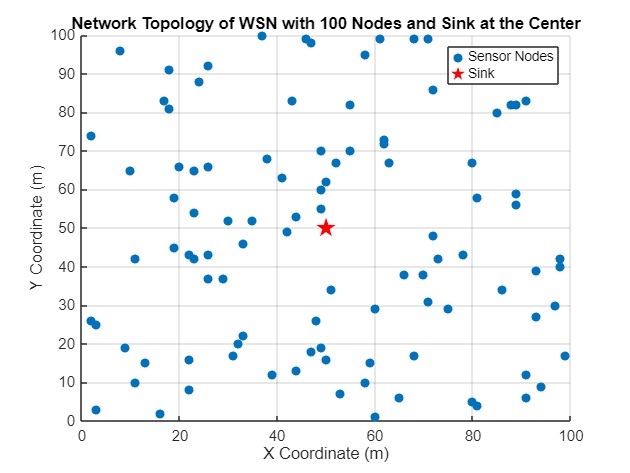

% Plot network topology
figure(1);
scatter(x, y, 'filled');                                                % Plot sensor nodes
hold on;
plot(sink(1), sink(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology of WSN with 100 Nodes and Sink at the Center');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Sink');
grid on;

                                                              ** Figure  [1]**

**                   The figure show the network with 100 sensors randomly deployed ,**

**                             and the sink at the center of the network at (50,50) .        **

**------------------------------------------------------------------------------------------------------------------------------------------------                     **

- **The simulation models sensor nodes transmitting data based on their distance from the sink. If the distance between a sensor and the sink is less than a defined threshold (d0), the sensor uses a short-range transmission model, which consumes less energy. For sensors farther than d0, a long-range transmission model is applied, which requires more energy due to increased transmission distance. A sensor node dies when its remaining energy is insufficient to meet the energy required for transmission, simulating the depletion of its energy resources over time.**

% Run the simulation until all nodes die
while alive_nodes > 0
    remaining_energy = E;                         % Record energy before updating for the current cycle
    for i = 1:N
        if E(i) > 0 && ~node_dead(i)              % If node is alive
            % Calculate distance to sink
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= d0
                % Short-range transmission
                energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2; % Energy for transmission
            else
                % Long-range transmission
                energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4; % Energy for transmission
            end
            % Check if the node has enough energy to transmit
            if E(i) > energy_consumed
                E(i) = E(i) - energy_consumed; % Deduct energy consumed for transmission
            else
                node_dead(i) = true; % Mark node as dead without setting energy to zero
                alive_nodes = alive_nodes - 1; % Reduce alive node count
                
                % Track dead nodes based on the cycle count
                if isempty(dead_nodes_T1) && alive_nodes == N-1 % First dead node (T1)
                    dead_nodes_T1 = find(node_dead); % Store indices of dead nodes at T1
                elseif isempty(dead_nodes_T2) && alive_nodes <= N/2 % Half nodes dead (T2)
                    dead_nodes_T2 = find(node_dead); % Store indices of dead nodes at T2
                elseif alive_nodes == 0 % Last node dies (T3)
                    dead_nodes_T3 = find(node_dead); % Store indices of all dead nodes at T3
                end

            end
        end
    end

    alive_nodes_per_cycle = [alive_nodes_per_cycle, alive_nodes]; % Update alive node count
    remaining_energy_per_cycle = [remaining_energy_per_cycle; E]; % Store remaining energy after this cycle
    cycles = cycles + 1; % Increment cycle count
end

- **The indicies , count of First nodes death : **

disp(['indecies of Dead nodes at T1: ', num2str(dead_nodes_T1)]);

indecies of Dead nodes at T1: 61


disp(length(dead_nodes_T1));

     1



- **The indicies ,count of half of nodes death  : **

disp(['indecies Dead nodes at T2: ', num2str(dead_nodes_T2)]);

indecies Dead nodes at T2: 1   3   4   6   7  13  15  18  19  22  24  25  26  28  33  34  35  36  41  42  43  44  45  48  50  51  58  59  60  61  62  63  65  68  69  70  71  76  77  81  85  86  88  90  91  92  93  94  96  97


disp(length(dead_nodes_T2)); 

    50



- **The indices , count of last nodes death : **

disp(['Dead nodes at T3: ', num2str(dead_nodes_T3)]);

Dead nodes at T3: 1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100


disp(length(dead_nodes_T3));

   100



**Part B****  Number of active nodes versus number of cycles , till the death of Last node : **

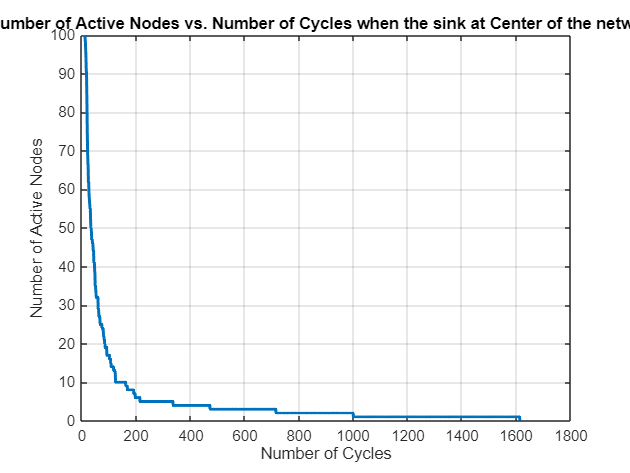

% Plot number of alive nodes versus cycles
figure(2);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles when the sink at Center of the network ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;

                                                                  ** Figure [2]**

**                        The figure show number of active nodes (not dead ) , versus the**

**                                     number of cycles , till the death of last node , when**

**                                                 the sink is at Center of the Network  . **

**--------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_1**** The network Life time , is indicated by T1, T2, T3 which indicates the Cycles at which First Node dies , Half of nodes dies , last Node dies : **

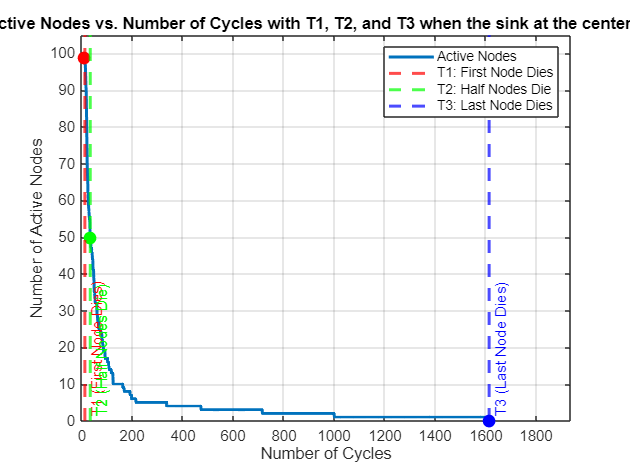

% Mark T1, T2, and T3 on the plot
T1 = find(alive_nodes_per_cycle == N-1, 1); % First node dies
T2 = find(alive_nodes_per_cycle <= N/2, 1); % Half of the nodes die
T3 = find(alive_nodes_per_cycle == 0, 1); % Last node dies

% Plot vertical lines to mark T1, T2, and T3
hold on;
xline(T1, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
xline(T2, 'g--', 'LineWidth', 2, 'Label', 'T2 (Half Nodes Die)', 'LabelVerticalAlignment', 'bottom');
xline(T3, 'b--', 'LineWidth', 2, 'Label', 'T3 (Last Node Dies)', 'LabelVerticalAlignment', 'bottom');

% Annotations for T1, T2, and T3
plot(T1, alive_nodes_per_cycle(T1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(T2, alive_nodes_per_cycle(T2), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
plot(T3, alive_nodes_per_cycle(T3), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');

% Adjust axis limits for wider scale
xlim([0 max(T3*1.2, length(alive_nodes_per_cycle))]); % Expands the x-axis by 20% more than T3
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels

% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1, T2, and T3 when the sink at the center of the network ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies', 'T2: Half Nodes Die', 'T3: Last Node Dies');
hold off;

**                                                                    Figure [3]**

**                     The figure show number of active nodes (not dead ) , versus the**

**                              number of cycles , till the death of last node , and indiction                 **

**                                               for T1 , T2, T3  when the sink is at the Center . **

**----------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_2 ****The Cycles at which First Node , Half of Nodes , Last Nodes dies : **

% Display the T1, T2, and T3 values 
disp(['T1 (First node dies): ', num2str(T1), ' cycles']);

T1 (First node dies): 12 cycles


disp(['T2 (Half nodes die): ', num2str(T2), ' cycles']);

T2 (Half nodes die): 33 cycles


disp(['T3 (Last node dies): ', num2str(T3), ' cycles']);

T3 (Last node dies): 1613 cycles


** ---------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_3**** Node death happens :  when the remaining energy at the node is less than the required energy for transimission , as when the energy at a node is less than the requried energy for transimission , by that it will transimit by negative energy , whether for short path or long path transimission model propagation models . **

**-----------------------------------------------------------------------------------------------------------------------------------------------------**

**Part D****  The remaining energy for the sensors nodes after T1 life time  : **

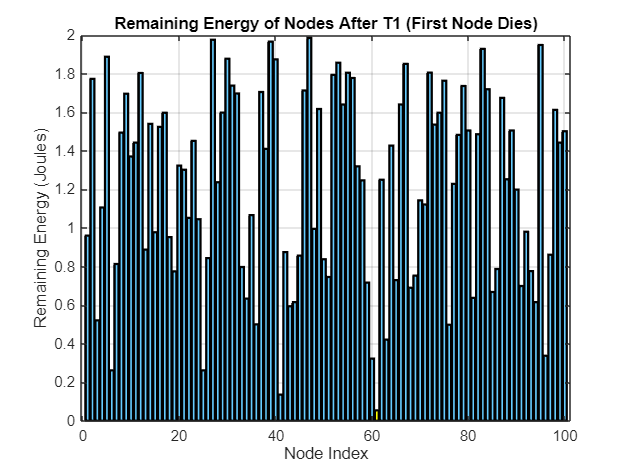

figure(4);
% Create a bar plot for the remaining energy at T1
bar_handles = bar(remaining_energy_per_cycle(T1, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T1)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

                                                                 **  Figure [4]**

**                    The figure shows the remaining energy at the network,after T1 life time ,                **

**                     in which the blue items indicates the remaining energy for alive nodes ,             **

**                        and the yellow items indicates the remaining energy for dead nodes. **

- **Observation ****: After T1 life time there's just one node dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies , while 2 indicates the sensors that haven't lose any energies , and node is considered  as dead node when the remaining energy is less than the requried energy for transimission .**

**-------------------------------------------------------------------------------------------------------------------------------------------------**

 **Part E****  The remaining energy for the sensors nodes after T2 life time : **

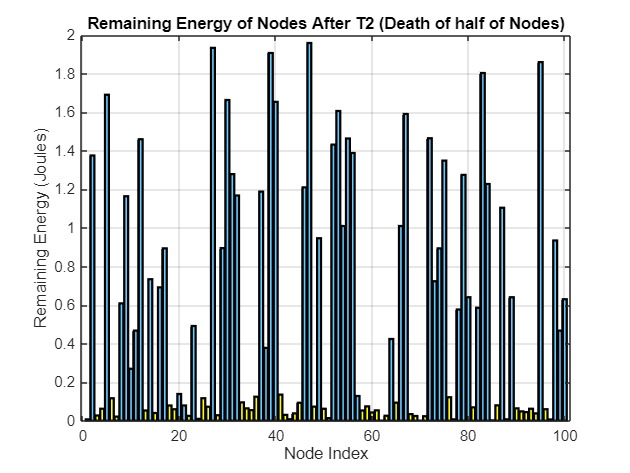

figure(5);
% Create a bar plot for the remaining energy at T2
bar_handles = bar(remaining_energy_per_cycle(T2, :)); 
title('Remaining Energy of Nodes After T2 (Death of half of Nodes)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T2)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle(T2, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle(T2, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                   Figure [5]**

**                    The figure shows the remaining energy at the network, after T2 life time ,                **

**                     in which the blue items indicates the remainng energy for alive nodes ,             **

**                        and the yellow items indicates the remaining energy for dead nodes. **

- **Observation ****: After T2 life time around half of nodes are dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies ,  2 indicates the sensors that haven't lose any energies , and node is considerede as dead node when the remaining energy is less than the requried energy for transimission .**

**---------------------------------------------------------------------------------------------------------------------------------------------------**

**Part F****  The remaining energy for the sensors nodes after T3 life time  : **

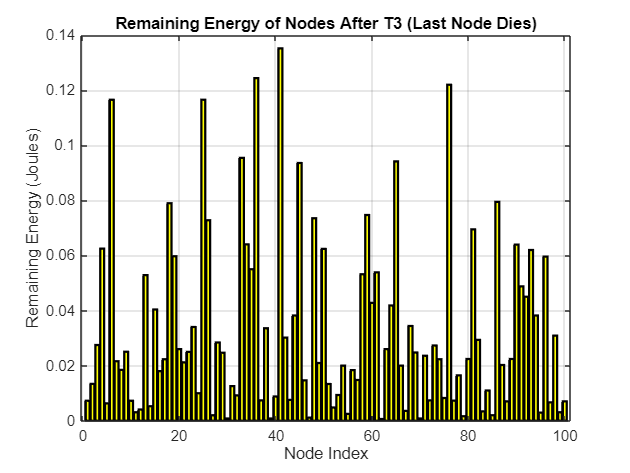

figure(6);
% Create a bar plot for the remaining energy at T3
bar_handles = bar(remaining_energy_per_cycle(T3, :)); 
title('Remaining Energy of Nodes After T3 (Last Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T3)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle(T3, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle(T3, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                 Figure [6]**

**                    The figure shows the remaining energy at the network , after T3 life time                  **

**                     whole nodes of blue color diseaper which indicates the death of whole nodes , **

**                                         while the yellow color indicates the nodes that are dead  . **

- **Observation ****: After T3 life time around whole of nodes are dead, in which it is become difficult to see some nodes with 2 joules , and most of nodes store energies less than the half of initial energies . **

**---------------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_A ****  The network topology with 100 sensors randomly deployed , with the sink at the top right corner  :                                                                                                                                                                                                                                                                                       **

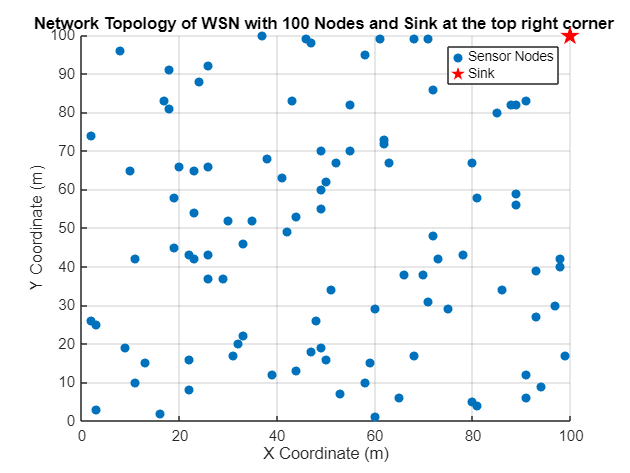

% Plot network topology
figure(7);
scatter(x, y, 'filled');                                                % Plot sensor nodes
hold on;
plot(sink_corner(1),sink_corner(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology of WSN with 100 Nodes and Sink at the top right corner ');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Sink');
grid on;

                                                                   ** Figure  [7]**

**                   The figure show the network with 100 sensors randomly deployed ,**

**                             and the sink at the top right corner of the network at (100,100) .     **

**---------------------------------------------------------------------------------------------------------------------------------------------------**

- **The simulation models sensor nodes transmitting data based on their distance from the sink. If the distance between a sensor and the sink is less than a defined threshold (d0), the sensor uses a short-range transmission model, which consumes less energy. For sensors farther than d0, a long-range transmission model is applied, which requires more energy due to increased transmission distance. A sensor node dies when its remaining energy is insufficient to meet the energy required for transmission, simulating the depletion of its energy resources over time.**

% Run the simulation until all corner nodes die
while alive_nodes_corners > 0
    remaining_energy_corners = E_corners;  % Record energy before updating for the current cycle
    dead_nodes_current_cycle_corners = [];  % Temporary array to store indices of nodes that die in the current cycle
    for i = 1:N
        if E_corners(i) > 0 && ~node_dead_corners(i)  % If node is alive
            % Calculate distance to sink (sink at corner)
            distance_to_sink_corner = sqrt((x(i) - sink_corner(1))^2 + (y(i) - sink_corner(2))^2);
            % Determine energy consumed based on transmission distance
            if distance_to_sink_corner <= d0
                % Short-range transmission
                energy_consumed_corner = k * Eelec + k * epsilon_fs * distance_to_sink_corner^2;  % Energy for transmission
            else
                % Long-range transmission
                energy_consumed_corner = k * Eelec + k * epsilon_mp * distance_to_sink_corner^4;  % Energy for transmission
            end
            % Check if the node has enough energy to transmit
            if E_corners(i) > energy_consumed_corner
                E_corners(i) = E_corners(i) - energy_consumed_corner;  % Deduct energy consumed for transmission
            else
                node_dead_corners(i) = true;  % Mark node as dead
                dead_nodes_current_cycle_corners = [dead_nodes_current_cycle_corners, i];  % Collect index of dead node
                alive_nodes_corners = alive_nodes_corners - 1;  % Reduce alive node count
            end
        end
    end
    % Track dead nodes for T1 (first node death)
    if alive_nodes_corners <= N - 1 && isempty(dead_nodes_T1_corners)
        % If the first node just died, save the dead nodes after this cycle
        dead_nodes_T1_corners = find(node_dead_corners);  % Save all dead nodes at T1
    end
    % Track dead nodes for T2 (half nodes dead)
    if alive_nodes_corners <= N / 2 && isempty(dead_nodes_T2_corners)
        % If half or more nodes have died, save the indices of all dead nodes up to this point
        dead_nodes_T2_corners = find(node_dead_corners);  % Save all dead nodes at T2
    end
    % Track dead nodes for T3 (all nodes dead)
    if alive_nodes_corners == 0
        % If all nodes are dead, save the indices of *all* dead nodes (i.e., the final set of nodes)
        dead_nodes_T3_corners = find(node_dead_corners);  % Save indices of all dead nodes at T3
    end
    
    % Update alive node count and remaining energy for each cycle
    alive_nodes_per_cycle_corners = [alive_nodes_per_cycle_corners, alive_nodes_corners];  % Store alive node count
    remaining_energy_per_cycle_corners = [remaining_energy_per_cycle_corners; E_corners];  % Store remaining energy after this cycle
    cycles_corners = cycles_corners + 1;  % Increment cycle count
end

**------------------------------------------------------------------------------------------------------------------------------------------------**

- **The indicies , count of First Node dies : **

disp(['indecies of Dead nodes at T1: ', num2str(dead_nodes_T1_corners)]);

indecies of Dead nodes at T1: 19  36  61  65  69  81  94  96


disp(length(dead_nodes_T1_corners));

     8



- **The indices , Count of Half or Nodes dies :  **

disp(['indecies Dead nodes at T2: ', num2str(dead_nodes_T2_corners)]);

indecies Dead nodes at T2: 1    3    4    5    6   10   11   12   14   16   17   18   19   20   21   24   25   28   29   31   32   33   35   36   37   38   40   41   43   44   49   54   57   58   60   61   65   66   67   69   71   73   76   78   80   81   84   90   91   94   96   99  100


disp(length(dead_nodes_T2_corners)); 

    53



- **The indices , count of Lst Nodes dies :  **

disp(['Dead nodes at T3: ', num2str(dead_nodes_T3_corners)]);

Dead nodes at T3: 1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100


disp(length(dead_nodes_T3_corners));

   100



**-----------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_B****  Number of active nodes versus number of cycles , till the death of Last node : **

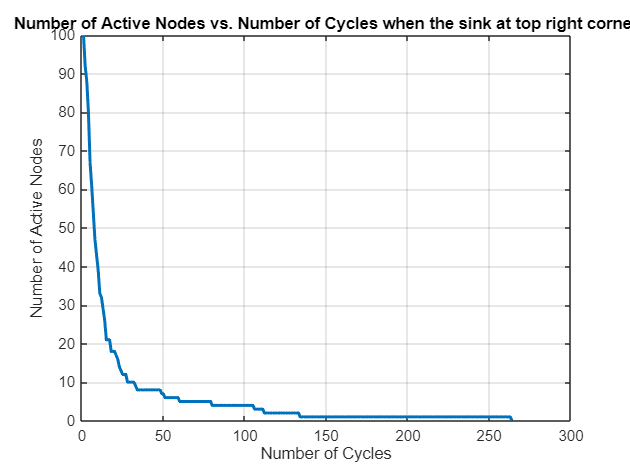

% Plot number of alive nodes versus cycles
figure(8);
plot(1:cycles_corners, alive_nodes_per_cycle_corners, 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles when the sink at top right corner');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;

                                                                  ** Figure [8]**

**                        The figure show number of active nodes (not dead ) , versus the**

**                                     number of cycles , till the death of last node , when the **

**                                           sink is located at the top right corner  . **

**--------------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_C_1**** The network Life time , is indicated by T1, T2, T3 which indicates the Cycles at which First Node dies , Half of nodes dies , last Node dies : **

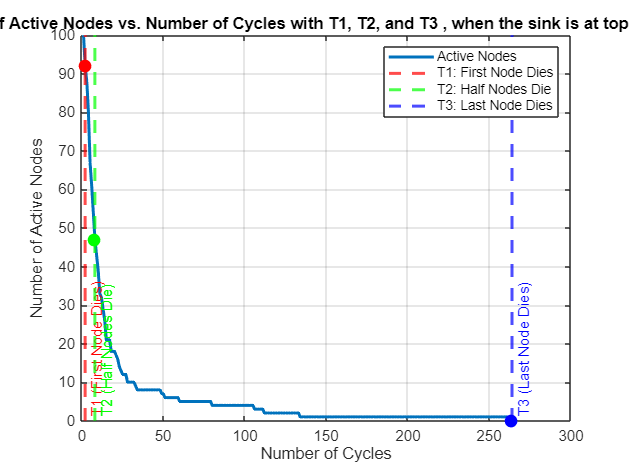

% Mark T1, T2, and T3 on the plot
T1_corners = find(alive_nodes_per_cycle_corners <= N-1, 1); % First node dies
T2_corners = find(alive_nodes_per_cycle_corners <= N/2, 1); % Half of the nodes die
T3_corners= find(alive_nodes_per_cycle_corners == 0, 1); % Last node dies
% Plot vertical lines to mark T1, T2, and T3
hold on;
xline(T1_corners, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
xline(T2_corners, 'g--', 'LineWidth', 2, 'Label', 'T2 (Half Nodes Die)', 'LabelVerticalAlignment', 'bottom');
xline(T3_corners, 'b--', 'LineWidth', 2, 'Label', 'T3 (Last Node Dies)', 'LabelVerticalAlignment', 'bottom');

% Annotations for T1, T2, and T3
plot(T1_corners, alive_nodes_per_cycle_corners(T1_corners), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(T2_corners, alive_nodes_per_cycle_corners(T2_corners), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
plot(T3_corners, alive_nodes_per_cycle_corners(T3_corners), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');

% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1, T2, and T3 , when the sink is at top right corner ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies', 'T2: Half Nodes Die', 'T3: Last Node Dies');
hold off;

**                                                                    Figure [9]**

**                     The figure show number of active nodes (not dead ) , versus the**

**                              number of cycles , till the death of last node , and indiction                 **

**                                       for T1 , T2, T3  when the sink is at the top right corner . **

**------------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_C_2 ****The Network Life Times at which First Node , Half of Nodes , Last Nodes dies : **

% Display the T1, T2, and T3 values in the command window
disp(['T1 (First node dies): ', num2str(T1_corners), ' cycles']);

T1 (First node dies): 2 cycles


disp(['T2 (Half nodes die): ', num2str(T2_corners), ' cycles']);

T2 (Half nodes die): 8 cycles


disp(['T3 (Last node dies): ', num2str(T3_corners), ' cycles']);

T3 (Last node dies): 264 cycles


** ----------------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_C_3**** Node death happens :  when the remaining energy at the node is less than the required energy for transimission , as when the energy at a node is less than the requried energy for transimission , by that it will transimit by negative energy , whether for short path or long path transimission model propagation models . **

**----------------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_D****  The remaining energy for the sensors nodes after T1 Life time  : **

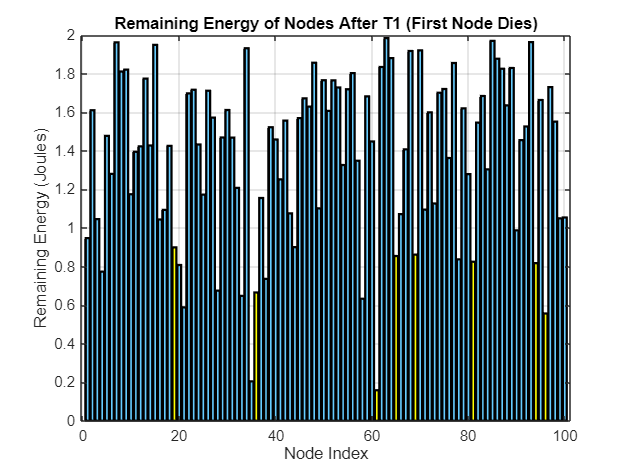

figure(10);
% Create a bar plot for the remaining energy at T1
bar_handles = bar(remaining_energy_per_cycle_corners(T1_corners, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T1_corners)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle_corners(T1_corners, i), ...
            'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle_corners(T1_corners, i), ...
            'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

                                                                 **  Figure [10]**

**                    The figure shows the remaining energy at the network,after T1 life time ,                **

**                     in which the blue items indicates the remaining energy for alive nodes ,             **

**                        and the yellow items indicates the remaining energy for dead nodes. **

- **Observation ****: After T1 life time there's one or more than one node dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies , while 2 indicates the sensors that haven't lose any energies , and node is considered as dead node when the remaining energy is less than the requried energy for transimission .**

**-----------------------------------------------------------------------------------------------------------------------------------------------**

 **Part G_E****  The remaining energy for the sensors nodes after T2 life time : **

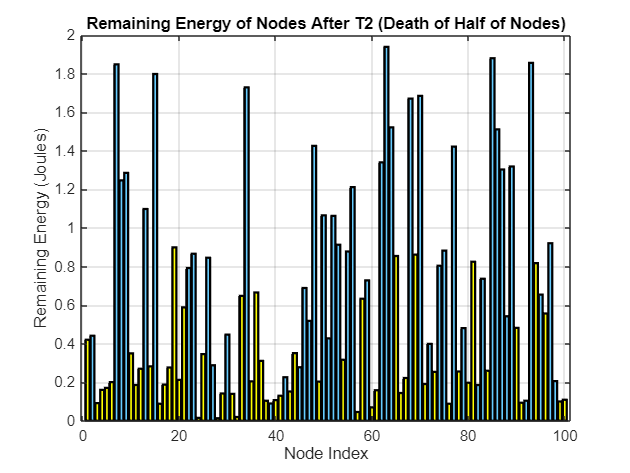

figure(11);
% Create a bar plot for the remaining energy at T2
bar_handles = bar(remaining_energy_per_cycle_corners(T2_corners, :)); 
title('Remaining Energy of Nodes After T2 (Death of Half of Nodes)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T2_corners)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle_corners(T2_corners, i), ...
            'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle_corners(T2_corners, i), ...
            'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                   Figure [11]**

**                    The figure shows the remaining energy at the network, after T2 life time ,                **

**                     in which the blue items indicates the remaining energy for alive nodes ,             **

**                        and the yellow items indicates the remaining energy for dead nodes. **

- **Observation ****: After T2 life time around half of nodes are dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies ,  2 indicates the sensors that haven't lose any energies , and node is considerede as dead node when the remaining energy is less than the requried energy for transimission .**

**-----------------------------------------------------------------------------------------------------------------------------------------------**

**Part G_F****  The remaining energy for the sensors nodes after T3 life time : **

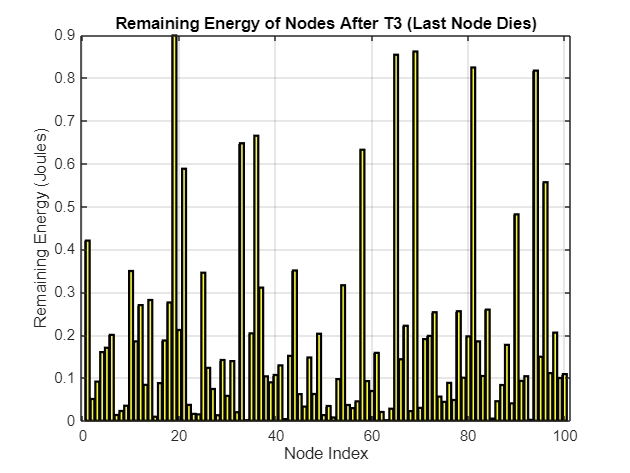

figure(12);
% Create a bar plot for the remaining energy at T3
bar_handles = bar(remaining_energy_per_cycle_corners(T3_corners, :)); 
title('Remaining Energy of Nodes After T3 (Last Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.4, 0.8, 1]; % Light cyan color for alive nodes
dead_color = [1, 1, 0];      % Phosphorescent yellow color for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T3_corners)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle_corners(T3_corners, i), ...
            'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle_corners(T3_corners, i), ...
            'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                 Figure [12]**

**                    The figure shows the remaining energy at the network , after T3 life time  ,                **

**                     whole nodes of blue color diseaper which indicates the death of whole nodes , **

**                                     while the yellow color indicates the nodes that are dead .**

- **Observation ****: After T3 Cycle around whole of nodes are dead , in which it is become difficult to see some nodes with 2 joules , and most of nodes store energies less than the half of initial energies . **

**----------------------------------------------------------------------------------------------------------------------------------------------------**

- **Conclusion :In the WSN simulation, it was observed that the number of cycles significantly increases when the sink is positioned at the center compared to when it is located at the top right corner. Specifically, sensors tend to deplete their energy more rapidly when the sink is at the top right corner. Furthermore, during the initial node deaths in the WSN with the sink at the top right corner, it was noted that multiple nodes can die simultaneously.Additionally, the remaining energy in the WSN nodes when the sink is at the center is generally less than the range observed when the sink is at the top right corner, even when all nodes are considered dead. This indicates that the remaining energy range in the WSN with the sink at the top right corner is considerably larger than when the sink is centrally located.**

**-----------------------------------------------------------------------------------------------------------------------------------------------------**

                                                                    **                                                    Done by. Nada tayel Khafagy **

                                                                    **                               under the supervision of DR.Smay Soliman && Ta. Heba selim**

                                                                    **                                   in Wireless Sensor network and IOT || CIE 510 || Fall 2024**

**                                                                                                                                            at UST || Zewail City **